# Initial setup

Configuring the working environment, clear workspace variables, and set random seed.

clear; clc; close all;
rng(42);

dataFolder = "data";
if ~isfolder(dataFolder)
    error("Data folder not found at %s", fullfile(pwd, dataFolder));
end

## Load data from zone_id

Loading electric vehicle charging energy data and weather parameters for the selected zone.

%zoneId=1;  %"Zone_509_Ponte Mammolo";
%zoneId=2;  %"Zone_116_Trastevere";
%zoneId=3;  %"Zone_125";
%zoneId=4;  %"Zone_705_Prenestino-Centocelle";;
%zoneId=5;  %"Eur 1201"
%zoneId=6;
%zoneId=7;  %"Zone_906_Arco_Di_Travertino"
%zoneId=8;  % Zona 1016
%zoneId=9;  %Zona 214 Trieste
%zoneId=10; % Zona 2004
zoneId=11; % Zona 2002
%zoneId=12; %Torvergata
fprintf("zoneId selected: %d \n", zoneId);

zoneId selected: 11 



zoneData = loadZoneData(dataFolder, zoneId);

Zone "Zone2002_Tor di Quinto6" loaded: 2784 rows (58 complete days, 48 steps/day).
Day breakdown: 41 working days (mean: 303.0 kWh), 17 non-working days (mean: 228.9 kWh).
Seasonal clusters identified (4 clusters):
  Cluster 1: 2023-02-15 (Wed) to 2023-02-28 (Tue) (14 days)
  Cluster 2: 2023-05-31 (Wed) to 2023-06-15 (Thu) (16 days)
  Cluster 3: 2023-07-12 (Wed) to 2023-07-25 (Tue) (14 days)
  Cluster 4: 2023-09-27 (Wed) to 2023-10-10 (Tue) (14 days)



hours = hour(zoneData.datetime) + minute(zoneData.datetime)/60;
zoneData.cosHour = cos(2 * pi * hours / 24);
zoneData.sinHour = sin(2 * pi * hours / 24);

## Variables and constants

Defining the lookback horizon, target variable, and candidate tabular features.

windowSize = 48;
targetName = "AAC_energy";

predictorNames = [ ...
    "lag1_energy", ...
    "lag2_energy", ...
    "lag48_energy", ...
    "rollMean24h", ...
    "rollStd24h", ...
    "temp", ...
    "cosHour", ...
    "sinHour", ...
    "holiday_proximity"];

numFeatures = numel(predictorNames);
fprintf("Lookback window size: %d half-hours (24 hours)\n", windowSize);

Lookback window size: 48 half-hours (24 hours)


fprintf("Number of tabular features: %d\n", numFeatures);

Number of tabular features: 9


fprintf("Target variable: %s\n", targetName);

Target variable: AAC_energy


## Split data into train, validation and test

Extracting causal lag features and partition into train, validation, and test splits.

[trainTable, valTable, testTable, normParams] = prepareTabularData(zoneData, windowSize, targetName);

Tabular split completed: 1824 train, 384 val, 384 test samples.



XTrain = trainTable(:, predictorNames);
yTrain = trainTable.(targetName);

XVal = valTable(:, predictorNames);
yVal = valTable.(targetName);

XTest = testTable(:, predictorNames);
yTest = testTable.(targetName);

## Feature Selection: Linear Correlation and Cross-Correlation Analysis

Inspecting linear correlation with target and sample cross-correlation on training split.

candidateVars = [targetName, predictorNames];
corrMatrix = corr(trainTable{:, candidateVars}, Rows="complete");
disp(table(candidateVars', round(corrMatrix(:, 1), 4), ...
    VariableNames=["Feature", "Correlation"]))

          Feature          Correlation
    ___________________    ___________

    "AAC_energy"                   1  
    "lag1_energy"             0.9192  
    "lag2_energy"             0.8138  
    "lag48_energy"              0.78  
    "rollMean24h"             0.1571  
    "rollStd24h"              0.1852  
    "temp"                    0.1849  
    "cosHour"                -0.6938  
    "sinHour"                -0.3005  
    "holiday_proximity"       -0.137  



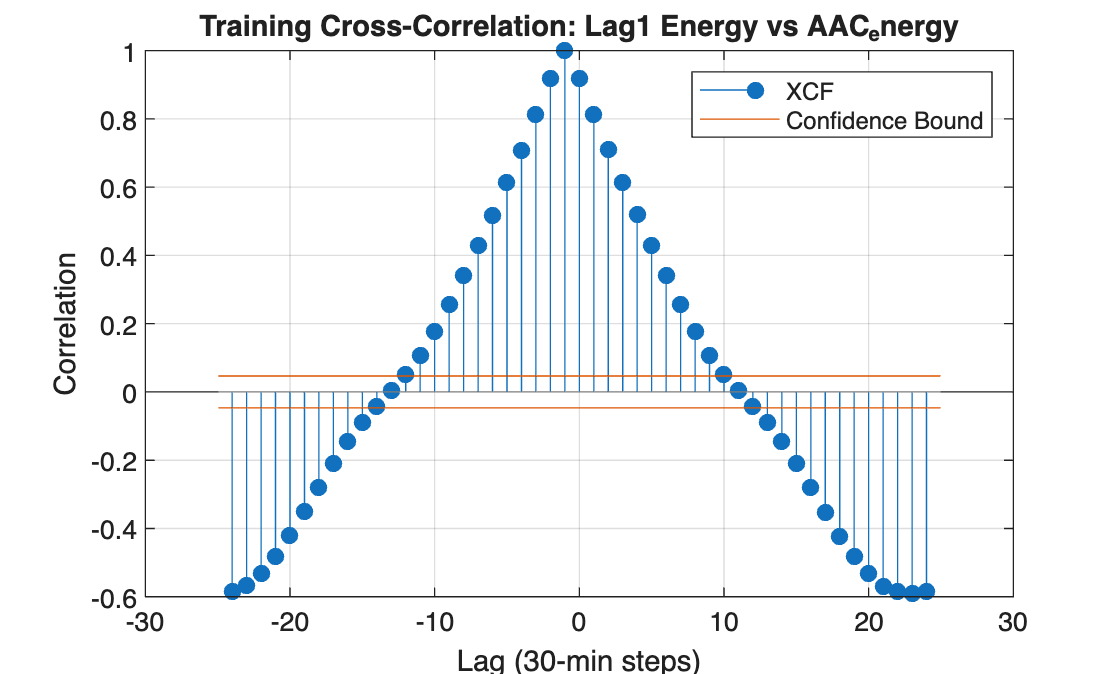


figure
crosscorr(trainTable.lag1_energy, trainTable.AAC_energy, NumLags=24)
title("Training Cross-Correlation: Lag1 Energy vs AAC_energy")
xlabel("Lag (30-min steps)")
ylabel("Correlation")
grid on

## Interactive Exploration with Regression Learner App

Launching the Regression Learner app to explore and compare regression models interactively.

%regressionLearner(trainTable(:, [predictorNames, targetName]), targetName);

## Train Regression Models

Train representative tabular machine learning models on the training dataset.

baggedTreesModel = fitrensemble(XTrain, yTrain, ...
    Method="Bag", ...
    NumLearningCycles=50);

fineTreeModel = fitrtree(XTrain, yTrain, ...
    MinLeafSize=4);

linearModel = fitrlinear(XTrain, yTrain);

## Test our models

Generate predictions on the hold-out test split and calculate evaluation metrics.

yPredBagged = predict(baggedTreesModel, XTest);
yPredTree = predict(fineTreeModel, XTest);
yPredLinear = predict(linearModel, XTest);

testRMSE = rmse(yPredBagged, yTest);
testMAE = mean(abs(yPredBagged - yTest));

rmseTree = rmse(yPredTree, yTest);
maeTree = mean(abs(yPredTree - yTest));

rmseLinear = rmse(yPredLinear, yTest);
maeLinear = mean(abs(yPredLinear - yTest));

fprintf("Bagged Trees - RMSE: %.2f kWh, MAE: %.2f kWh\n", testRMSE, testMAE);

Bagged Trees - RMSE: 92.52 kWh, MAE: 65.58 kWh


fprintf("Fine Tree    - RMSE: %.2f kWh, MAE: %.2f kWh\n", rmseTree, maeTree);

Fine Tree    - RMSE: 111.33 kWh, MAE: 76.70 kWh


fprintf("Linear Model - RMSE: %.2f kWh, MAE: %.2f kWh\n", rmseLinear, maeLinear);

Linear Model - RMSE: 101.76 kWh, MAE: 76.48 kWh


## Evaluate against persistence baseline

Compare the primary model against the lazy persistence baseline y(t+1) = y(t).

lazyPred = testTable.lag1_energy;
lazyRMSE = rmse(lazyPred, yTest);
lazyMAE = mean(abs(lazyPred - yTest));

meanTarget = mean(yTest);
cvRMSE = (testRMSE / meanTarget) * 100;
lazyCV = (lazyRMSE / meanTarget) * 100;
errorReduction = (1 - testRMSE / lazyRMSE) * 100;

fprintf("Test RMSE: %.2f kWh (CV(RMSE): %.2f%%)\n", testRMSE, cvRMSE);

Test RMSE: 92.52 kWh (CV(RMSE): 32.42%)


fprintf("Test MAE:  %.2f kWh\n", testMAE);

Test MAE:  65.58 kWh


fprintf("Lazy Persistence RMSE: %.2f kWh (CV(RMSE): %.2f%%)\n", lazyRMSE, lazyCV);

Lazy Persistence RMSE: 108.04 kWh (CV(RMSE): 37.86%)


fprintf("Bagged Trees Error Reduction over Lazy: %.2f%%\n", errorReduction);

Bagged Trees Error Reduction over Lazy: 14.37%


## Visual Storytelling: Measured vs Predicted Charging Load

Plot measured charging load against model predictions across the test period (gaps removed).

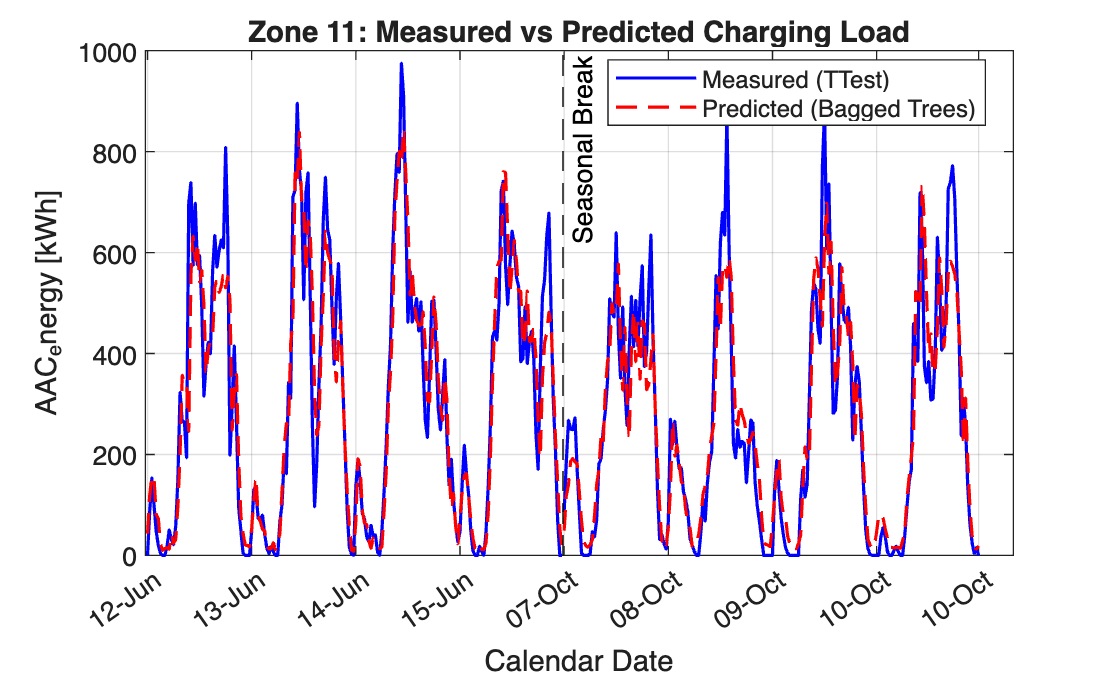

gapIndices = find(diff(testTable.datetime) > minutes(30));
numSamples = height(testTable);
xVec = 1:numSamples;

xPlot = xVec;
yTestPlot = yTest;
yPredPlot = yPredBagged;

for g = numel(gapIndices):-1:1
    idx = gapIndices(g);
    xPlot = [xPlot(1:idx), idx + 0.5, xPlot(idx+1:end)];
    yTestPlot = [yTestPlot(1:idx); NaN; yTestPlot(idx+1:end)];
    yPredPlot = [yPredPlot(1:idx); NaN; yPredPlot(idx+1:end)];
end

figure
plot(xPlot, yTestPlot, "b-", LineWidth=1.2)
hold on
plot(xPlot, yPredPlot, "r--", LineWidth=1.2)

for g = 1:numel(gapIndices)
    xline(gapIndices(g) + 0.5, "k--", "Seasonal Break", LabelVerticalAlignment="top", LineWidth=0.8)
end

tickIdx = unique([1:48:numSamples, numSamples]);
xticks(tickIdx)
xticklabels(string(testTable.datetime(tickIdx), "dd-MMM"))
xtickangle(35)
xlabel("Calendar Date")
ylabel("AAC_energy [kWh]")
title(sprintf("Zone %d: Measured vs Predicted Charging Load", zoneId))
legend(["Measured (TTest)", "Predicted (Bagged Trees)"], Location="best")
grid on

## Residual Diagnostics and Autocorrelation Analysis

Analyze forecast residuals on the first continuous test block to verify white noise behavior.

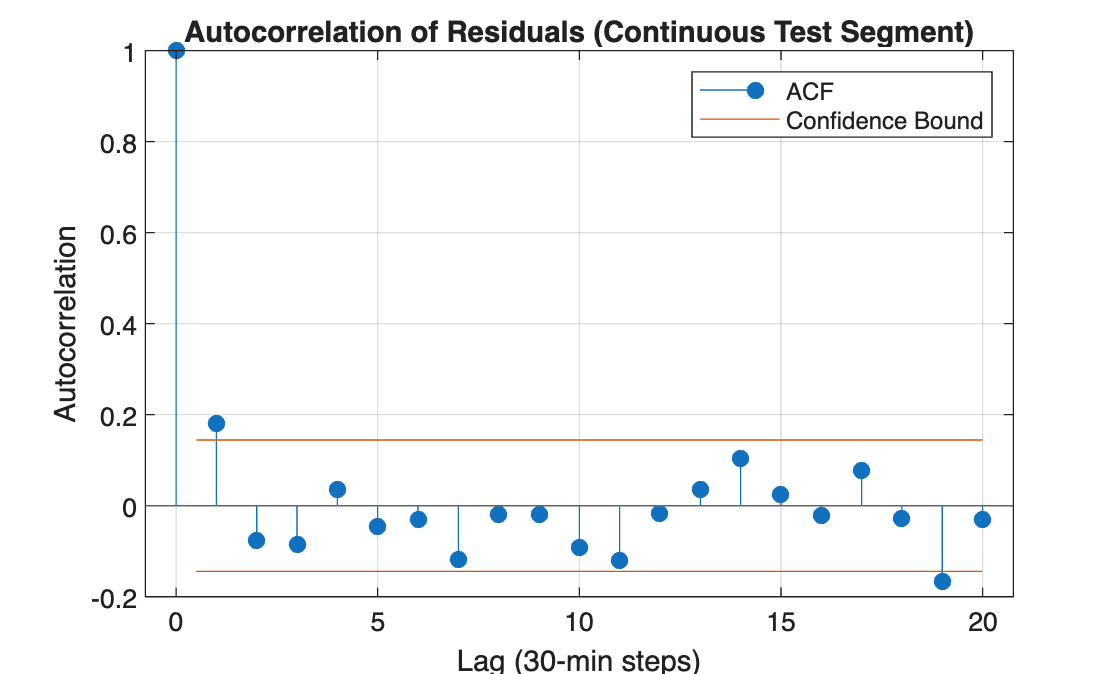

residuals = double(yTest - yPredBagged);

timeGaps = [false; diff(testTable.datetime) > minutes(30)];
firstBreakIdx = find(timeGaps, 1);
if isempty(firstBreakIdx)
    continuousResiduals = residuals;
else
    continuousResiduals = residuals(1 : firstBreakIdx - 1);
end

figure
autocorr(continuousResiduals, NumLags=20)
title("Autocorrelation of Residuals (Continuous Test Segment)")
xlabel("Lag (30-min steps)")
ylabel("Autocorrelation")
grid on


lagsToTest = 10;
[h, pValue, stat, cValue] = lbqtest(continuousResiduals, Lags=lagsToTest);
fprintf("Ljung-Box Q-stat: %.2f (Critical: %.2f), p-value: %.4f\n", stat, cValue, pValue);

Ljung-Box Q-stat: 14.45 (Critical: 18.31), p-value: 0.1535


if h == 0
    disp("Fail to reject H0: Residuals are consistent with white noise.");
else
    disp("Reject H0: Residuals exhibit remaining autocorrelation.");
end

Fail to reject H0: Residuals are consistent with white noise.


## Save Model

Save the trained regression model, normalization parameters, and metrics to disk.

timestamp = string(datetime("now", "Format", "yyyyMMdd_HHmm"));
modelDir = fullfile("models", "RegressionLearner", sprintf("Zone%d", zoneId));
if ~exist(modelDir, "dir")
    mkdir(modelDir);
end
modelFile = fullfile(modelDir, sprintf("BaggedTrees_Zone%d_RMSE%.1f_%s.mat", zoneId, testRMSE, timestamp));
save(modelFile, "baggedTreesModel", "normParams", "predictorNames", "testRMSE");
fprintf("Model saved: %s\n", modelFile);

Model saved: models/RegressionLearner/Zone11/BaggedTrees_Zone11_RMSE92.5_20260913_2215.mat
